# Stability Criteria

Rover shall be designed to safely accommodate a 20° slope in any direction at a speed of at least 1 m/sec and including the ability to start and stop.

## Parameters

Slope $\theta =20$ degrees

Mass $m = 670$ kg

Gravity $g = 1.62 \frac{m}{s^2{$ 

r = wheel radius (m)

h = height (m) between the wheel axes and CoM

l = length (m) between the front and rear axles

a = length (m) between the front axle and CoM

ax = longitudinal acceleration $\frac{m}{s^2}$

## Longitudinal Dynamic Stability


$$N_1 = mg\bigg(\bigg(1-\frac{a}{l}\bigg)cos\theta-\bigg(\frac{h}{l}+\frac{r}{l}\bigg)sin\theta-\frac{a_x}{g}\bigg)$$



$$N_2 = mg\bigg(\frac{a}{l}cos\theta+\bigg(\frac{h}{l}+\frac{r}{l}\bigg)sin\theta+\frac{a_x}{g}\bigg)$$



$$T_1 = \frac{N_1}{N_1+N_2}(mgsin\theta+ma_x)$$



$$T_2 = \frac{N_2}{N_1+N_2}(mgsin\theta+ma_x)$$


clear vars
clc
close all

theta = deg2rad(20); % Slope (rad)
m = 670; %kg, total (max) rover mass
g = 1.62; %m/s^2, accel due to gravity on the Moon

syms h l ax a r slope

N1 = m*g*((1-(a/l))*cos(theta)-((h/l)+(r/l))*sin(theta)-(ax/g))/2; % Normal force (N) on each of the front two wheels
N2 = m*g*((a/l)*cos(theta)+((h/l)+(r/l))*sin(theta)-(ax/g))/2; % Normal force (N) on each of the rear two wheels
T_RR = (N2/(N1+N2))*m*g*sin(theta)+m*ax; % Torque (Nm) applied by the rear right wheel
T_RL = (N2/(N1+N2))*m*g*sin(theta)+m*ax; % Torque (Nm) applied by the rear left wheel
T_FR = (N1/(N1+N2))*m*g*sin(theta)+m*ax; % Torque (Nm) applied by the front right wheel
T_FL = (N1/(N1+N2))*m*g*sin(theta)+m*ax; % Torque (Nm) applied by the front left wheel

h_ =1;
l_ =3.8;
r_ =0.6;
a_ =1.2;
ax_=0.5;


N1_ = double(subs(N1,[h l ax a r],[h_ l_ ax_ a_ r_]))

N1_ = 103.2743

N2_ = double(subs(N2,[h l ax a r],[h_ l_ ax_ a_ r_]))

N2_ = 71.6969

T_F = double(subs(T_FR,[h l ax a r],[h_ l_ ax_ a_ r_]))

T_F = 554.1124

T_R = double(subs(T_RR,[h l ax a r],[h_ l_ ax_ a_ r_]))

T_R = 487.1162

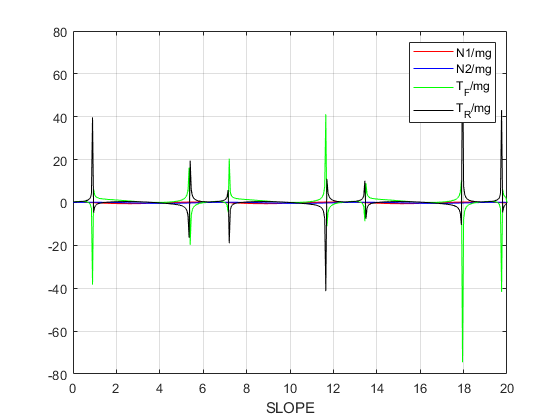


slope = 0:0.05:20;
N1_list = zeros(1,length(slope));
N2_list = zeros(1,length(slope));
T_R_list = zeros(1,length(slope));
T_F_list = zeros(1,length(slope));

for i = 1:400
    N1_list(i) = m*g*((1-(a_/l_))*cos(slope(i))-((h_/l_)+(r_/l_))*sin(slope(i))-(ax_/g))/2;
    N2_list(i) = m*g*((a_/l_)*cos(slope(i))+((h_/l_)+(r_/l_))*sin(slope(i))-(ax_/g))/2;
    T_F_list(i) = (N1_list(i)/(N1_list(i)+N2_list(i)))*m*g*sin(slope(i))+m*ax_;
    T_R_list(i) = (N2_list(i)/(N1_list(i)+N2_list(i)))*m*g*sin(slope(i))+m*ax_; 
end
plot(slope,N1_list./(m*g),'red')
hold on
plot(slope,N2_list./(m*g),'blue')
hold on
plot(slope,T_F_list./(m*g),'green')
hold on
plot(slope, T_R_list./(m*g), 'black')
hold off
legend('N1/mg','N2/mg','T_{F}/mg','T_{R}/mg')
xlabel('SLOPE')

grid on

### Overturn Limits

- For dynamic case:

#### 
$$(1-\frac{a}{l})cos{\theta_{limit}} - (\frac{h}{l}+\frac{r}{l})sin{\theta_{limit}} = \frac{a_x}{g}
$$


syms theta_l_d
eqn = (1-(a_/l_))*cos(theta_l_d) - ((h_+r_/l_)*sin(theta_l_d) == (ax_/g));
Theta_limit_d = rad2deg(double(solve(eqn,theta_l_d)))

Theta_limit_d =    15.4593
  164.5407


- For static case: 


$$tan{\theta_{limit}} = \frac{l-a}{h+r}$$


syms theta_l_s
Theta_limit_s = rad2deg(atan((l_-a_)/(h_+r_)))

Theta_limit_s = 58.3925

#### Limiting acceleration on flat ground : $a_{x,limit} = g(1-\frac{a}{l})$

a_x_limit = g*(1-(a_/l_))

a_x_limit = 1.1084

### Limits on slope

- Acceleration :  

 
$$\frac{dv}{dt}\Bigr|_{lim} = g[(\frac{l-a}{r+h})cos{\theta} - sin{\theta}]$$


dvdt_a = g*(((l_-a_)*cos(theta)/(r_+h_)) - sin(theta));
Limited_Acceleration = [num2str(dvdt_a),'  m/s^2'];
disp(Limited_Acceleration)

1.9197  m/s^2


- Deceleration


$$\frac{dv}{dt}\Bigr|_{lim} =- g[(\frac{a}{r+h})cos{\theta} + sin{\theta}]$$


dvdt_d = -g*(((a_)*cos(theta)/(r_+h_)) + sin(theta));
Limited_Acceleration = [num2str(dvdt_d),'  m/s^2'];
disp(Limited_Acceleration)

-1.6958  m/s^2


### Impulsive Pitch-over Criteria


$$V_{limit} \leq \sqrt{2g(\sqrt{a^2+h^2} -h)}$$


v_limit = sqrt(2*g*(sqrt(a_^2+h_^2)-h_));
V_limit = [num2str(v_limit),'  m/s'];
disp(V_limit)

1.3495  m/s


### Turning radius on a slope

$radius = \frac{v^2}{g}[\frac{a.cos{\theta}}{h} - sin{\theta}]^{-1}$, where v is the velocity of the vehicle

radius = (v_limit^2/g)*((a_/h_)*cos(theta) - sin(theta))^(-1); 
Radius = [num2str(radius),'  m  (radius based on V_limit)'];
disp(Radius)

1.4309  m  (radius based on V_limit)
